**An example of MATLAB code that uses the Viola-Jones algorithm for eye detection from a photo. It can detect eyes for multiple people in an image**.

*This code uses the *`EyePairBig` *cascade object detector, which is suitable for detecting both eyes of a person in an image. You can experiment with different cascade classifiers for eye detection, such as *`'EyePairSmall'`* or *`'Eye'`*, to see which one works best for your specific image dataset.*

`Remember to have the ``Computer Vision System Toolbox`` installed in your MATLAB environment for this code to work properly.`

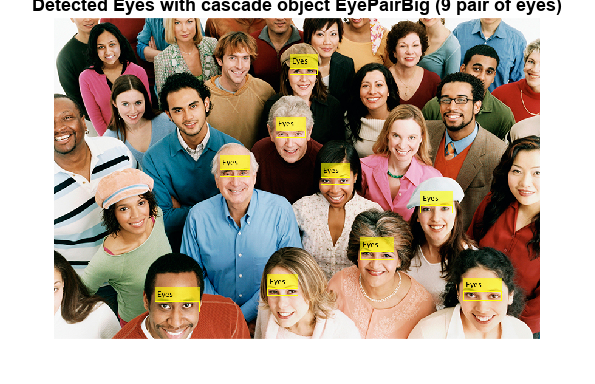

% Specify the URL link of the image
imageUrl = 'https://www.ppic.org/wp-content/uploads/Crowd-of-Diverse-People_800x528.jpg';
image = webread(imageUrl);

% Convert the image to grayscale
grayImage = rgb2gray(image);

% Create a cascade object detector for eye detection
eyeDetector = vision.CascadeObjectDetector('EyePairBig');

% Detect eyes in the image
bbox = step(eyeDetector, grayImage);

% Count the number of eyes detected
numEyes = size(bbox, 1);

% Draw rectangles around the detected eyes
detectedImage = insertObjectAnnotation(image, 'rectangle', bbox, 'Eyes');

% Display the original image with detected eyes
figure;
imshow(detectedImage);
title(['Detected Eyes with cascade object EyePairBig (', num2str(numEyes), ' pair of eyes)']);

Using another cascade object ''EyePairSmall'.

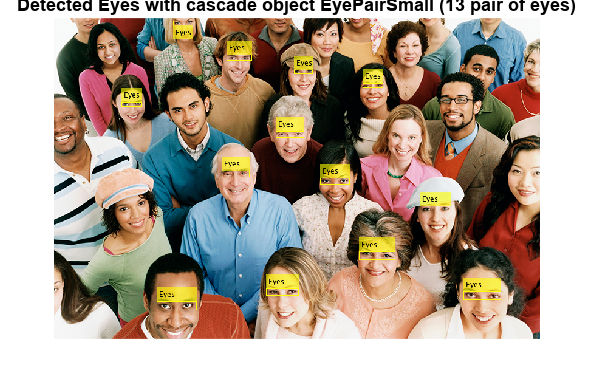


% Convert the image to grayscale
grayImage = rgb2gray(image);

% Create a cascade object detector for eye detection
eyeDetector = vision.CascadeObjectDetector('EyePairSmall');

% Detect eyes in the image
bbox = step(eyeDetector, grayImage);

% Count the number of eyes detected
numEyes = size(bbox, 1);

% Draw rectangles around the detected eyes
detectedImage = insertObjectAnnotation(image, 'rectangle', bbox, 'Eyes');

% Display the original image with detected eyes
figure;
imshow(detectedImage);
title(['Detected Eyes with cascade object EyePairSmall (', num2str(numEyes), ' pair of eyes)']);

Using another cascade object ''LeftEye"

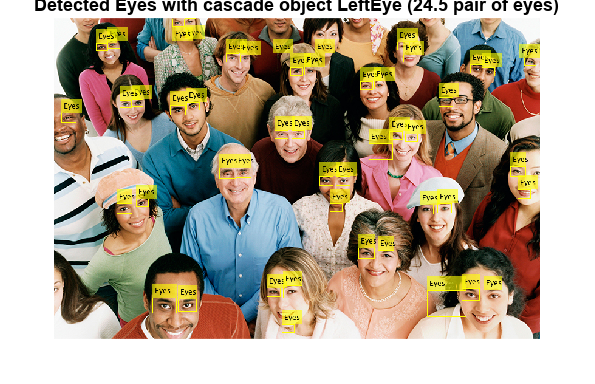

% Convert the image to grayscale
grayImage = rgb2gray(image);

% Create a cascade object detector for eye detection
eyeDetector = vision.CascadeObjectDetector('LeftEye');

% Detect eyes in the image
bbox = step(eyeDetector, grayImage);

% Count the number of eyes detected
numEyes = size(bbox, 1);

% Draw rectangles around the detected eyes
detectedImage = insertObjectAnnotation(image, 'rectangle', bbox, 'Eyes');

% Display the original image with detected eyes
figure;
imshow(detectedImage);
title('Image with Detected Eyes with cascade object LeftEye');

title(['Detected Eyes with cascade object LeftEye (', num2str(numEyes/2), ' pair of eyes)']);

# **Use another cascades classifiers provided by the Computer Vision System Toolbox in MATLAB for detection porposes, there are several other pre-trained models available for different object detection tasks:**

- `'UpperBody'`: Detects upper body regions, including the head, torso, and arms.

- `'LowerBody'`: Detects lower body regions, including the waist, legs, and feet.

- `'FullBody'`: Detects full-body regions, including the head, torso, arms, waist, legs, and feet.

- `'ProfileFace'`: Detects profile faces, which are faces seen from the side.

- `'Nose'`: Detects nose regions in frontal face images.

- `'EyePairSmall'`: Detects eye pairs or individual eyes.

- `'FrontalCatFace'`: Detects frontal cat faces.

- `'FrontalDogFace'`: Detects frontal dog faces.

- `'CarFront'`: Detects front views of cars.

`These are just a few examples, and there are many more cascade classifiers available for various object detection tasks. You can explore the full list of available cascade classifiers in the MATLAB documentation for the vision.CascadeObjectDetector function.`

`When using these cascade classifiers, you can follow a similar approach as shown in the previous code examples to detect and annotate the corresponding objects in an image.`

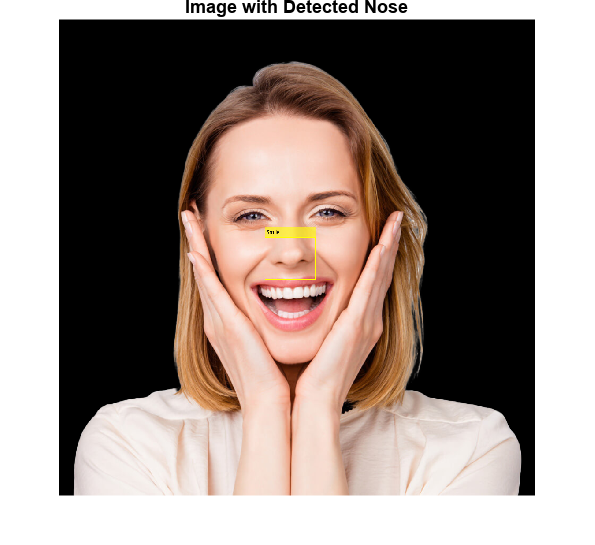

% for example detect mouth in a face 
% Specify the URL link of the image
imageUrl = 'https://lovetosmile.ie/wp-content/uploads/2023/02/2-new.png';
image = webread(imageUrl);


% Convert the image to grayscale
grayImage = rgb2gray(image);

% Create a cascade object detector for smile detection
noseDetector = vision.CascadeObjectDetector('Nose');

% Detect smiles in the image
bbox = step(noseDetector, grayImage);

% Draw rectangles around the detected smiles
detectedImage = insertObjectAnnotation(image, 'rectangle', bbox, 'Smile');

% Display the original image with detected smiles
figure;
imshow(detectedImage);
title('Image with Detected Nose');